# **CP241 - Lab Assignment 4**

**QUESTION 1: **Ball and beam system given as:


$$(\frac{J}{R^2} + m) \ddot{r} - mgsin\alpha - mr\dot{\alpha}^2 = 0
\\
\alpha = \frac{d}{L}\theta$$


I can write the above 2nd order differential equation in $r$ into two first order differntial equations with $x_1 =r$ (position), and $x_2 =\dot{r} =\dot{x_1 }$ (velocity), as:


$$\dot{x}_1 = x_2
\\
\dot{x}_2 = (mgsin\alpha + m{x_1}\dot{\alpha}^2)(\frac{R^2}{J + mR^2})
$$
   

Where, $\alpha =\frac{d}{L}\theta$ and therefore, $\dot{\alpha} =\frac{d}{L}\dot{\theta}$

Given,

$\begin{array}{l}
r_i =0\ldotp 25\;\\
\dot{r_i } =0
\end{array}$ Initial conditions: position (in m.) and velocity.

$r_{\textrm{ref}} =0\ldotp 25\sin \;t+0\ldotp 25$ (in metres). 

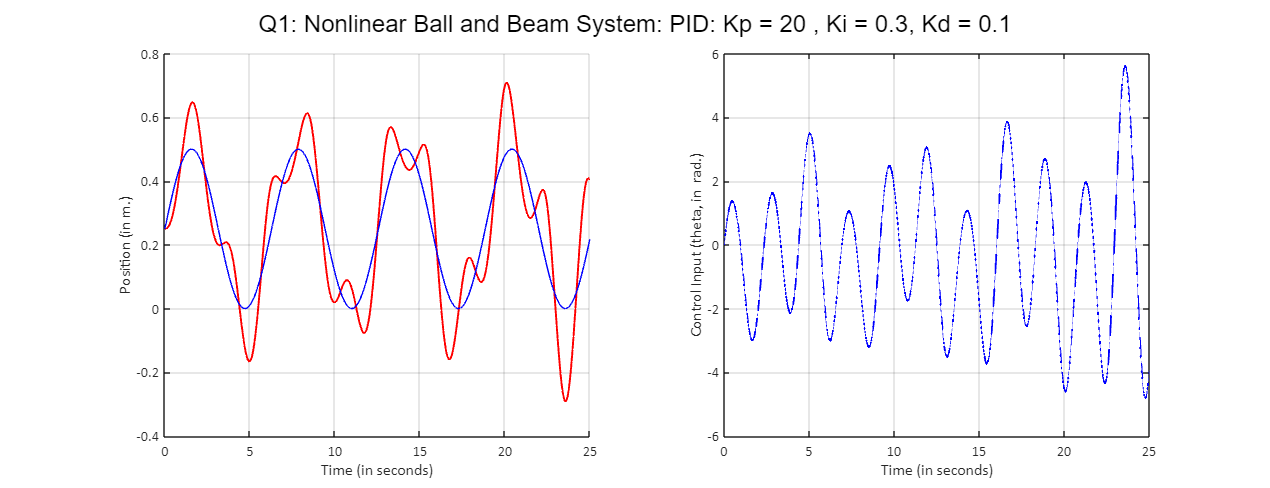

clc
clear all
close all

%format long 
global e_sum theta_prev error_prev;
global Kp Ki Kd;

global u_q1; %for storing the control inputs
global time_q1; %for storing the corresponding time

u_q1 = 0;
time_q1 =0;

e_sum = 0;
theta_prev = 0;
error_prev = 0;

% Setting the PID gains
Kp = 20;
Ki = 0.3;
Kd = 0.1;

% Declaring the constants
m=0.1;      % Kg
R= 0.02;    % m
J=1e-5;     % kgm^2
L=1;        % m
d=0.05;     % lever length
g=9.8;       % gravity
tspan= [0 25]; % given time span
x0 = [0.25; 0];  % Initial conditions (position and velocity). The THIRD ROW is dummy to STORE CONTROL input (theta) values.

h = 0.001; % time step for RK4



[t, states] = LA4_RK4(@(t,x) q1_dynamics(m,R,J,L,d,g,h,x,t), tspan, h ,x0);


%%% Plotting the respones / states %%%
fig1 = figure();
subplot(1,2,1);
hold on
plot(t,states(1,:),'r', 'LineWidth', 1.2);
plot(t,r_ref(t), 'b')
hold off
xlim([0 25])
xlabel('Time (in seconds)');
ylabel('Position (in m.)');
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
%legend(["Actual Position"],['Reference'])
grid on

subplot(1,2,2)
plot(time_q1, u_q1,'b', 'LineWidth', 1.2); % the third column in 'x' stores the control input for my case.
xlabel('Time (in seconds)');
ylabel('Control Input (theta, in  rad.)');

set(gca, 'FontName', 'Calibri', 'FontSize', 9);
sgtitle('Q1: Nonlinear Ball and Beam System: PID: Kp = 20 , Ki = 0.3, Kd = 0.1')
xlim([0 25])
fig1.Position = [10,10,1300,500];
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
grid on;

**----------------------------------------------------------------------------------------END OF Q1--------------------------------------------------------------------------------------------------------**

**QUESTION-2(a) Pole Placement at (i) (-1,-2) , and (ii) (-2+i, -2-i) **

$J = \left[ \matrix{\frac{\partial f_1}{ \partial x_1} &  \frac{\partial f_1}{ \partial x_2  } \cr \frac{\partial f_1}{ \partial x_1} &  \frac{\partial f_2 }{\partial x_2}} \right]$ = $\left[ \matrix{0 &  1 \cr m \dot{\alpha}^2 (\frac{R^2}{J + mR^2})  & 0 } \right]$ (at r = r_dot = 0) at zero input (theta = theta_dot =0): $A  = \left[ \matrix{0 &  1 \cr 0  & 0 } \right]$

we have linearized system around origin with zero input (theta = alpha = 0) ) as:

$\dot{x} = \left[ \matrix{0 &  1 \cr 0  & 0 } \right]x$ , Since we want full state feedback, $B  = \left[ \matrix{1  \cr 1} \right]$

So the input for state feedback (with zero reference) is actually: $u=-\textrm{kx}$  ;  where, $k$ is the state feedback gain matrix, and $x$ is the state.

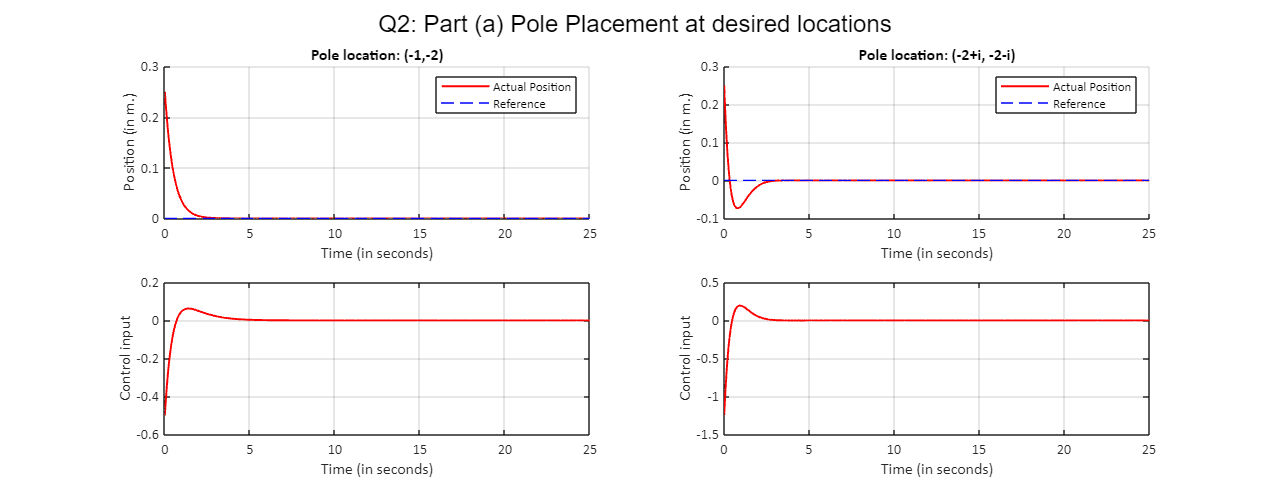

A = [0 1 ; 0 0];    % The state matrix linearized about origin
B = [1;1];          % For full state feedback

ref = 0;            % Zero reference, as given in question.
x0 = [0.25 ; 0];    % Initial conditions as given in Q1: x1 = r = position = 0.25m ; x2 = r_dot = velocity = 0 m/s.
tspan = [0 25];

desired_pole_location_i = [-1 -2];          % Desired pole location i %% PART (i)
desired_pole_location_ii = [-2+i, -2-i];    % Desired pole location ii %% PART (ii)

k1 = place(A,B,desired_pole_location_i);    % feedback gain matrix for placing pole to location_i
k2 = place(A,B,desired_pole_location_ii);   % feedback gain matrix for placing pole to location_i


A_cl_1 = A - B*k1;  % New state matrix with poles at location i
A_cl_2 = A - B*k2;  % New state matrix with poles at location ii


%Declaring the dynamics for both the cases:
f1 = @(t,x)([A_cl_1*[x(1) ; x(2)] + B*ref]);
f2 = @(t,x)([A_cl_2*[x(1) ; x(2)] + B*ref]);


% Solving the dynamics using ode45
[t_q2parta_1, states_q2parta_1] = ode45(f1, tspan, x0);
[t_q2parta_2, states_q2parta_2] = ode45(f2, tspan, x0);

% Finding the input : u = -k*x
u_q2parta_1 = -k1*transpose(states_q2parta_1);
u_q2parta_2 = -k2*transpose(states_q2parta_2);


% Finding the control inputs: basically u = -k*states (i.e. -k*x)

%%% Plotting the respones / states %%%
fig2 = figure();
subplot(2,2,1);
title('Pole location: (-1,-2)')
hold on
plot(t_q2parta_1, states_q2parta_1(:,1),'r', 'LineWidth', 1.2);
plot(t_q2parta_1,ref*ones(length(t_q2parta_1)), '--b')
hold off
xlim([0 25])
xlabel('Time (in seconds)');
ylabel('Position (in m.)');
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
legend(["Actual Position", "Reference"])
grid on

subplot(2,2,2)
title('Pole location: (-2+i, -2-i)');
hold on
plot(t_q2parta_2, states_q2parta_2(:,1),'r', 'LineWidth', 1.2);
plot(t_q2parta_2,ref*ones(length(t_q2parta_2)), '--b')
hold off
xlabel('Time (in seconds)');
ylabel('Position (in m.)');
legend(["Actual Position", "Reference"])
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
sgtitle('Q2: Part (a) Pole Placement at desired locations')
xlim([0 25])
grid on

subplot(2,2,3);
plot(t_q2parta_1, u_q2parta_1,'r', 'LineWidth', 1.2);
xlim([0 25])
xlabel('Time (in seconds)');
ylabel('Control input');
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
grid on

subplot(2,2,4);
plot(t_q2parta_2, u_q2parta_2,'r', 'LineWidth', 1.2);
xlim([0 25])
xlabel('Time (in seconds)');
ylabel('Control input');
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
grid on

fig2.Position = [10,10,1300,500];
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
grid on;

**QUESTION-2 Part (b) Control through LQR:**

Given,  $Q = \left[ \matrix{1 &  0 \cr 0  & 10 } \right]$ and $R = 2$ . LQR will be used to get the feedback gain matrix for optimal pole locations.

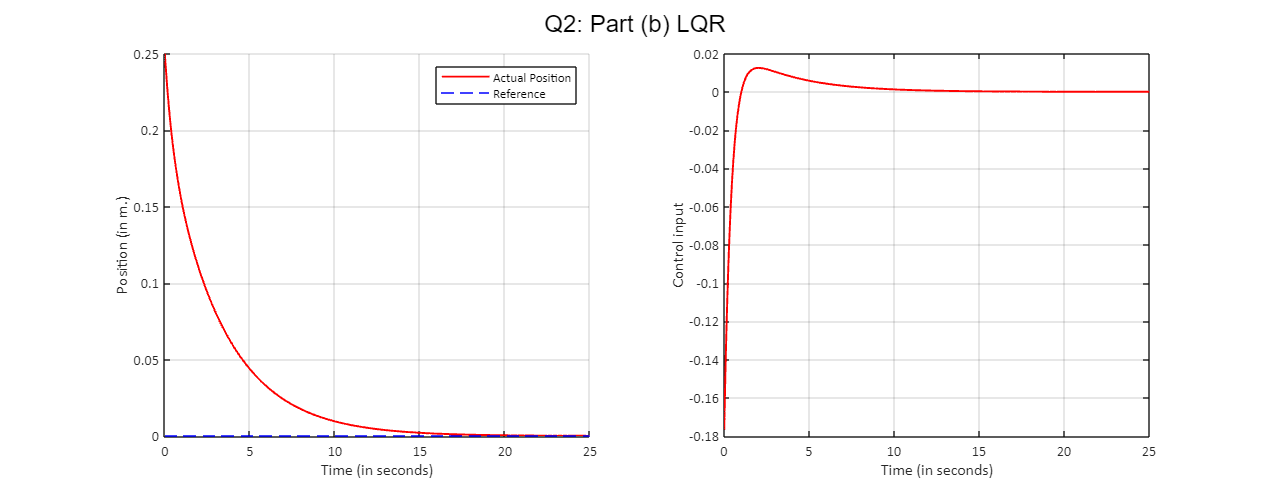

A = [0 1 ; 0 0];    % The state matrix linearized about origin
B = [1;1];          % For full state feedback

ref = 0;            % Zero eference, as given in question.
x0 = [0.25 ; 0];    % Initial conditions as given in Q1: x1 = r = position = 0.25m ; x2 = r_dot = velocity = 0 m/s.
tspan = [0 25];     % Time span as given.

% LQR %
Q = [1 0 ; 0 10];
R = 2;
[K,S,P] = lqr(A,B,Q,R);     % K = optimal feedback gain matrix.

A_cl_lqr = A - B*K;  % New state matrix with poles at location i

%Declaring the dynamics for both the cases:
f_q2_lqr = @(t,x)([A_cl_lqr*[x(1) ; x(2)] + B*ref]);


% Solving the dynamics using ode45
[t_q2_lqr, states_q2_lqr] = ode45(f_q2_lqr, tspan, x0);

% Getting the input used : u = -k*x
u_q2_lqr = -K*transpose(states_q2_lqr);


fig3 = figure();
subplot(1,2,1);
sgtitle('Q2: Part (b) LQR')
hold on
plot(t_q2_lqr, states_q2_lqr(:,1),'r', 'LineWidth', 1.2);
plot(t_q2_lqr,ref*ones(length(t_q2_lqr)), '--b')
hold off
xlim([0 25])
xlabel('Time (in seconds)');
ylabel('Position (in m.)');
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
legend(["Actual Position", "Reference"])
grid on

subplot(1,2,2)
plot(t_q2_lqr, u_q2_lqr,'r', 'LineWidth', 1.2);
xlim([0 25])
xlabel('Time (in seconds)');
ylabel('Control input');
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
grid on

fig3.Position = [10,10,1300,500];
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
grid on;

disp(['The Optimal gain matrix obtained by LQR is: [' num2str(K(:).') ']']) ;

The Optimal gain matrix obtained by LQR is: [0.70711      1.9224]


disp(['The Optimal pole positions obtained by LQR is: [' num2str(P(:).') ']']) ;

The Optimal pole positions obtained by LQR is: [-0.30408     -2.3254]


**----------------------------------------------------------------------------------------------END OF Q2--------------------------------------------------------------------------------------------------**

**QUESTION-3**

Executing cascaded PID for double loop control of PMDC motor.

                                                                            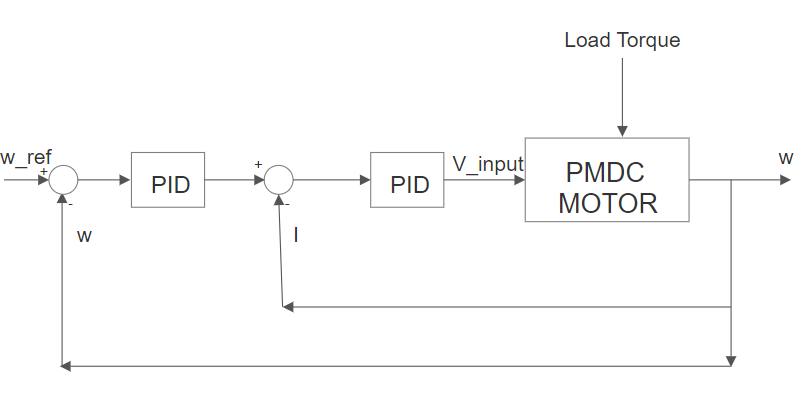

Simulation will be for 180 seconds. 

Initially the motor is off (speed, current = 0,0). 

- The reference motor speed is 50 rad/sec. 

- The load torque is constant at 50 Nm. for first 90 seconds. Then, an exponentially growing sinusoidal disturbance is given for 20 seconds (from t=90 to t=110). Then finally the load torque is again constant at 60 Nm. (Please see the plot below). For the mathematical expression of disturbance, see function 'Tload' below.

- Motor parameters were taken from the Assignment 3 (please the function 'q3_dynamics').

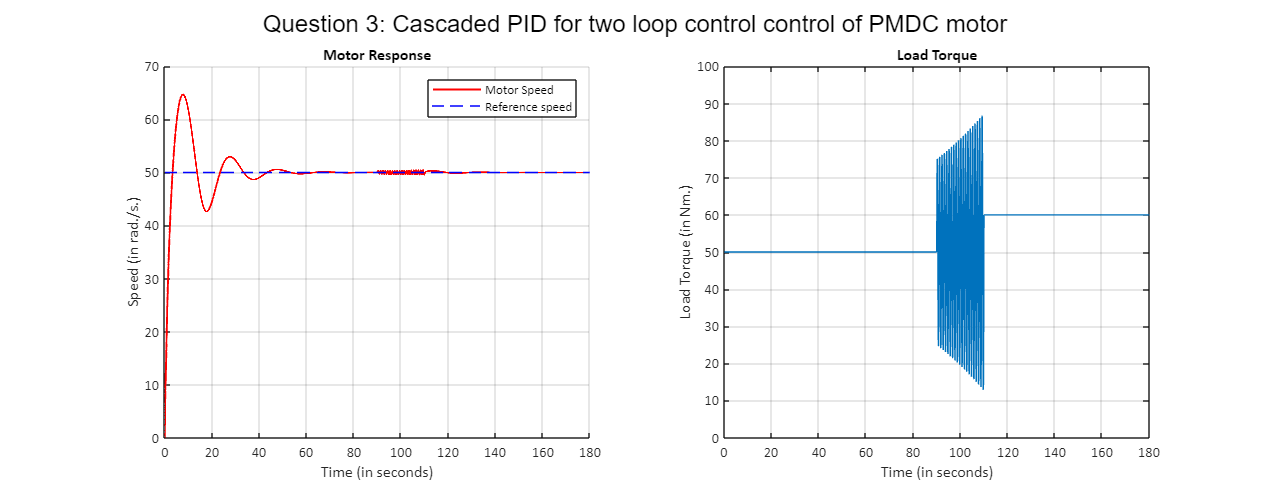

clear all % Clearing previous stuff because matlab was crashing. 

% Declaring global variables
global e_w_sum e_I_sum error_w_prev error_I_prev; % To store previous errors to get derivate term

global Kp_o Ki_o Kd_o; %Outer loop gains
global Kp_i Ki_i Kd_i; % Inner loop gains

global u_q3; %for storing the control inputs
global time_q3; %for storing the corresponding time

u_q3 = 0;
time_q3 =0;

e_w_sum=0;
e_I_sum=0;

error_w_prev=0;
error_I_prev=0;

% Setting the PID gains

%outer loop % Assumed through trial and error 
Kp_o = 4;
Ki_o = 2;
Kd_o = 1;

%inner loop % Assumed through trial and error 
Kp_i = 2;
Ki_i=0.4;
Kd_i=0.01;

h = 0.01; %time step
tspan= [0 180]; % given time span
x0 = [0;0];  % Initial conditions (current and speed)


ref_speed = 50; %radian per second.
load_torque = 50;

% Solving the state equation %
[t, states3] = LA4_RK4(@(t,x) q3_dynamics(x,h, ref_speed, load_torque, t) ,tspan, h, x0);

%Getting the load torques values used
load_torques = zeros(length(t), 1);
for i=1:length(t)
    load_torques(i) = Tload(t(i));
end

fig4 = figure();
subplot(1,2,1)
hold on
plot(t,states3(2,:),'r', 'LineWidth', 1.2);
plot(t, ref_speed*ones(length(t), 1), '--b');
hold off
grid on
legend(["Motor Speed" "Reference speed"])
title('Motor Response')
xlabel('Time (in seconds)');
ylabel('Speed (in rad./s.)');
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
grid on

subplot(1,2,2)
plot(t,load_torques)
ylim([0 100]);
xlim(tspan)
grid on
title('Load Torque')
xlabel('Time (in seconds)');
ylabel('Load Torque (in Nm.)');
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
grid on

sgtitle('Question 3: Cascaded PID for two loop control control of PMDC motor')
fig4.Position = [10,10,1300,500];
set(gca, 'FontName', 'Calibri', 'FontSize', 9);
grid on;

fprintf("The disturbance torque(RIGHT) and its effect on motor speed (LEFT) is shown in above plots. \nPlease refer to the Tload function below to check the disturbance equation.")

The disturbance torque(RIGHT) and its effect on motor speed (LEFT) is shown in above plots. 
Please refer to the Tload function below to check the disturbance equation.

**---------------------------------------------------------------------------------------END OF Q3---------------------------------------------------------------------------------------------------------**

**FUNCTION DECLARATIONS**

Used 5 functions:

- q1_dynamics : the dynamic equations and controller for question 1 ball and beam system.

- r_ref : to get the reference position signal for question 1 ball and beam system.

- q3_dynamics: the dynamic equations and dual loop controller for question 3 PMDC motor.

- Tload : for load torque for question 3. Includes disturbance.

- LA4_RK4 : the runge kutta method code (used in q1, q3) I took from my assignment 1.

function x_dot = q1_dynamics(m,R,J,L,d,g, h, x,t)
    % System Dynamics
    global e_sum theta_prev error_prev;
    global u_q1;
    global time_q1;
    global Kp Ki Kd;

    error = r_ref(t) - x(1);
    delta_t = h;
    
    e_sum = e_sum + delta_t*error;

    % Control input
    theta = Kp*(error) + Kd*(error-error_prev)/(delta_t) + Ki*e_sum;
    alpha = d*theta/L;
    alpha_dot = d*(theta-theta_prev)/(delta_t*L);
    
    %System dynamics
    x_dot(1,1) = x(2);
    x_dot(2,1) = (m*g*sin(alpha) + m*(x(1))*(alpha_dot^2))*((R^2)/(J + m*(R^2) ));
    
    theta_prev = theta;
    error_prev = error;
    u_q1 = [u_q1; theta];
    time_q1 = [time_q1;t];
end

%%%%%%
function ref = r_ref(t)
    ref = 0.25*sin(t) + 0.25;
end

%%%%%%%
function x_dot = q3_dynamics(x,h, ref_speed, load_torque, t)
    global e_sum theta_prev error_prev;
    global e_w_sum e_I_sum error_w_prev error_I_prev;
    global u_q3;
    global time_q3;
    global Kp_o Ki_o Kd_o; %Outer loop gains
    global Kp_i Ki_i Kd_i; % Inner loop gains

    Ra=0.1;     % Ohms
    La= 0.01;   % H
    J=10;       % kgm^2
    B=0.01;     % Nms
    Kb=1;       % Vs/rad 
    Kt=1;       % 1Nm/A

    error = ref_speed - x(2);
    delta_t = h;
    load_torque = Tload(t);

    error_w = ref_speed - x(2);
    e_w_sum = e_w_sum + delta_t*error_w;
    I_ref = Kp_o*(error_w) + Kd_o*(error_w-error_w_prev)/(delta_t) + Ki_o*e_w_sum; %Reference input current

    error_I = I_ref - x(1);
    e_I_sum = e_I_sum + delta_t*error_I;
    V_input = Kp_i*(error_I) + Kd_i*(error_I-error_I_prev)/(delta_t) + Ki_i*e_I_sum; %Control input voltage

    x_dot(1,1) = -(Ra/La)*x(1) - (x(2))*(Kb/La)*x(2) + V_input/La;
    x_dot(2,1) = (Kt/J)*x(1) - (x(2))*(B/J) + load_torque/J; %T_load()

    error_prev = error;
    error_w_prev = error_w;
    error_I_prev = error_I;
    u_q3 = [u_q3 ; V_input];
    time_q3 = [time_q3;t];
end

%%%%%%%%%%%
function t_load = Tload(t)
    if t<=90
        t_load = 50;

    elseif 90<t && t<=110
        t_load = 50 +25*exp((t-90)/50)*sin(2*pi*(t-90));

    else
        t_load = 60;
    end
end
  

%%%%%%%%%%%%
function [t, x] = LA4_RK4(f, tspan, h, x0)
    t = [tspan(1):h:tspan(2)];
    max_samples = length(t);
    x = x0;
    for i = 1:max_samples-1
        k1 = h*f(t(i), x(:,i));
        k2 = h*f(t(i)+h/2, x(:,i)+k1/2);
        k3 = h*f(t(i)+h/2, x(:,i)+k2/2);
        k4 = h*f(t(i), x(:,i)+k3/3);
        x(:,i+1) = x(:,i) + (k1+2*k2+2*k3+k4)*(1/6);
    end
end



